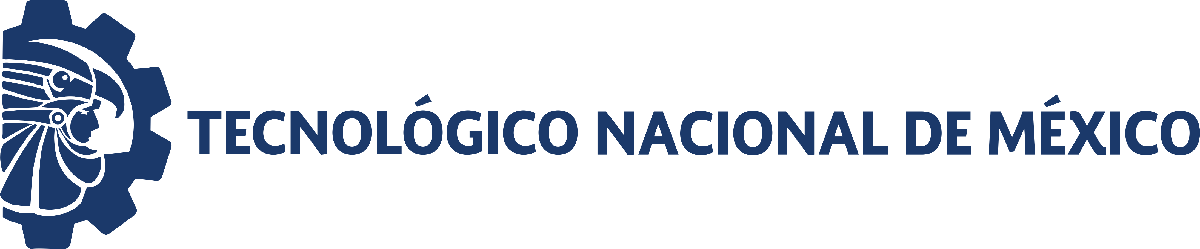                                 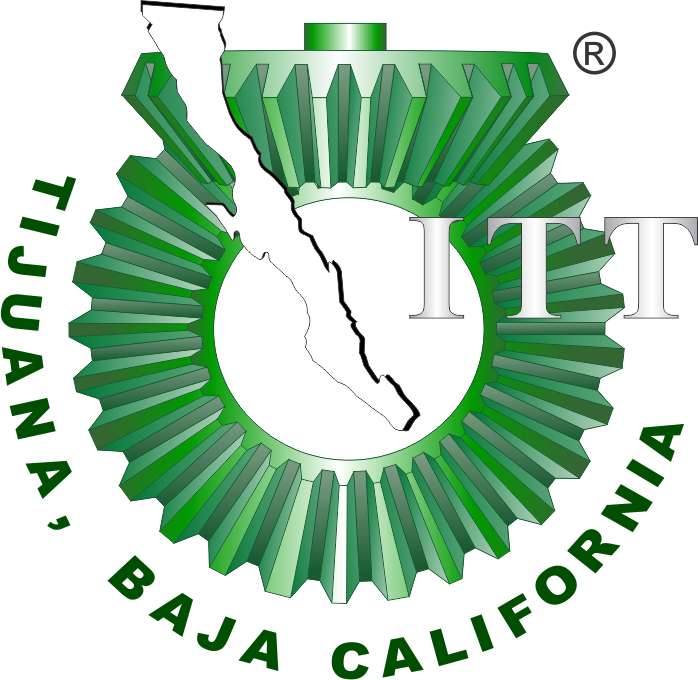

# Práctica 4: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                     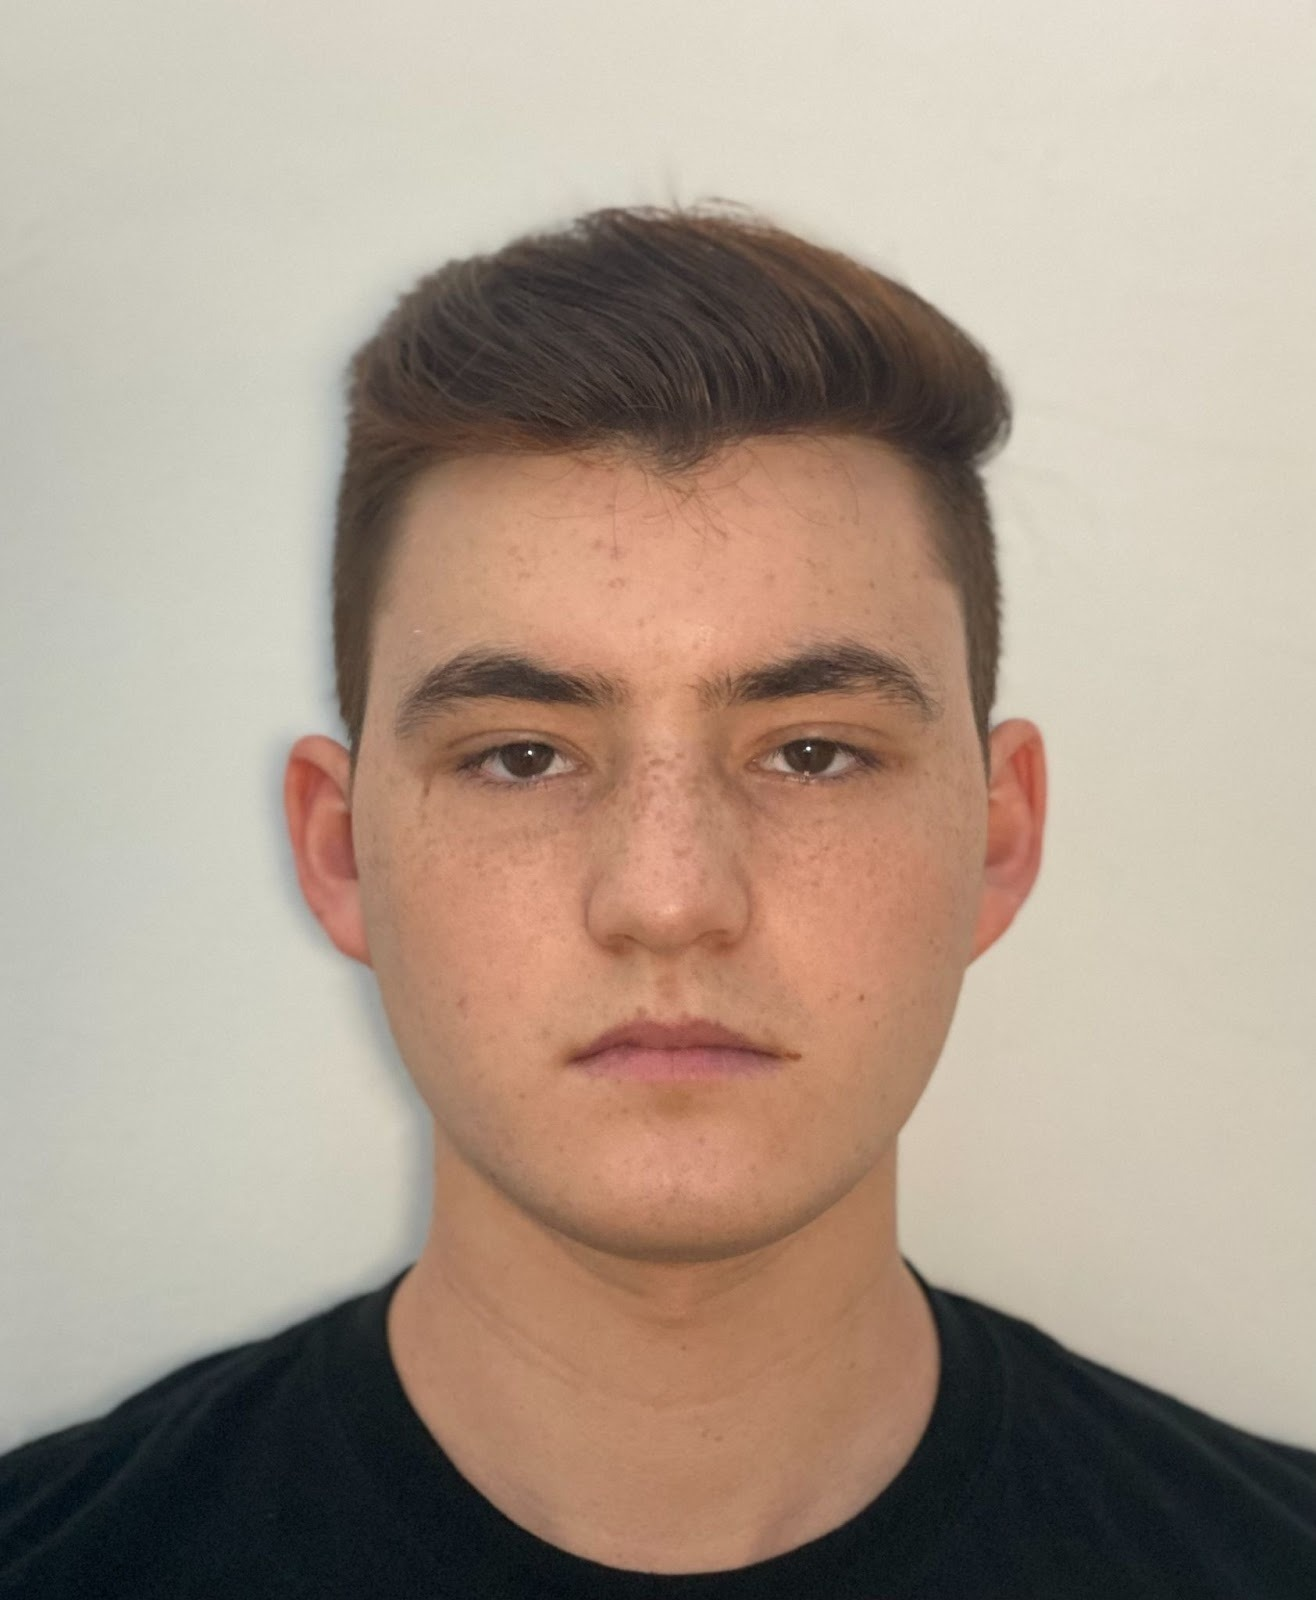

Nombre del alumno: Marco Antonio Campoy Alegria

Número de control: 21212145

Correo institucional: L21212145@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameter.StopTime = '15';
parameter.Solver = 'ode15s';
parameter.MaxStep = '1E-3';
x = sim(file,parameter);

## Respuesta del sistema

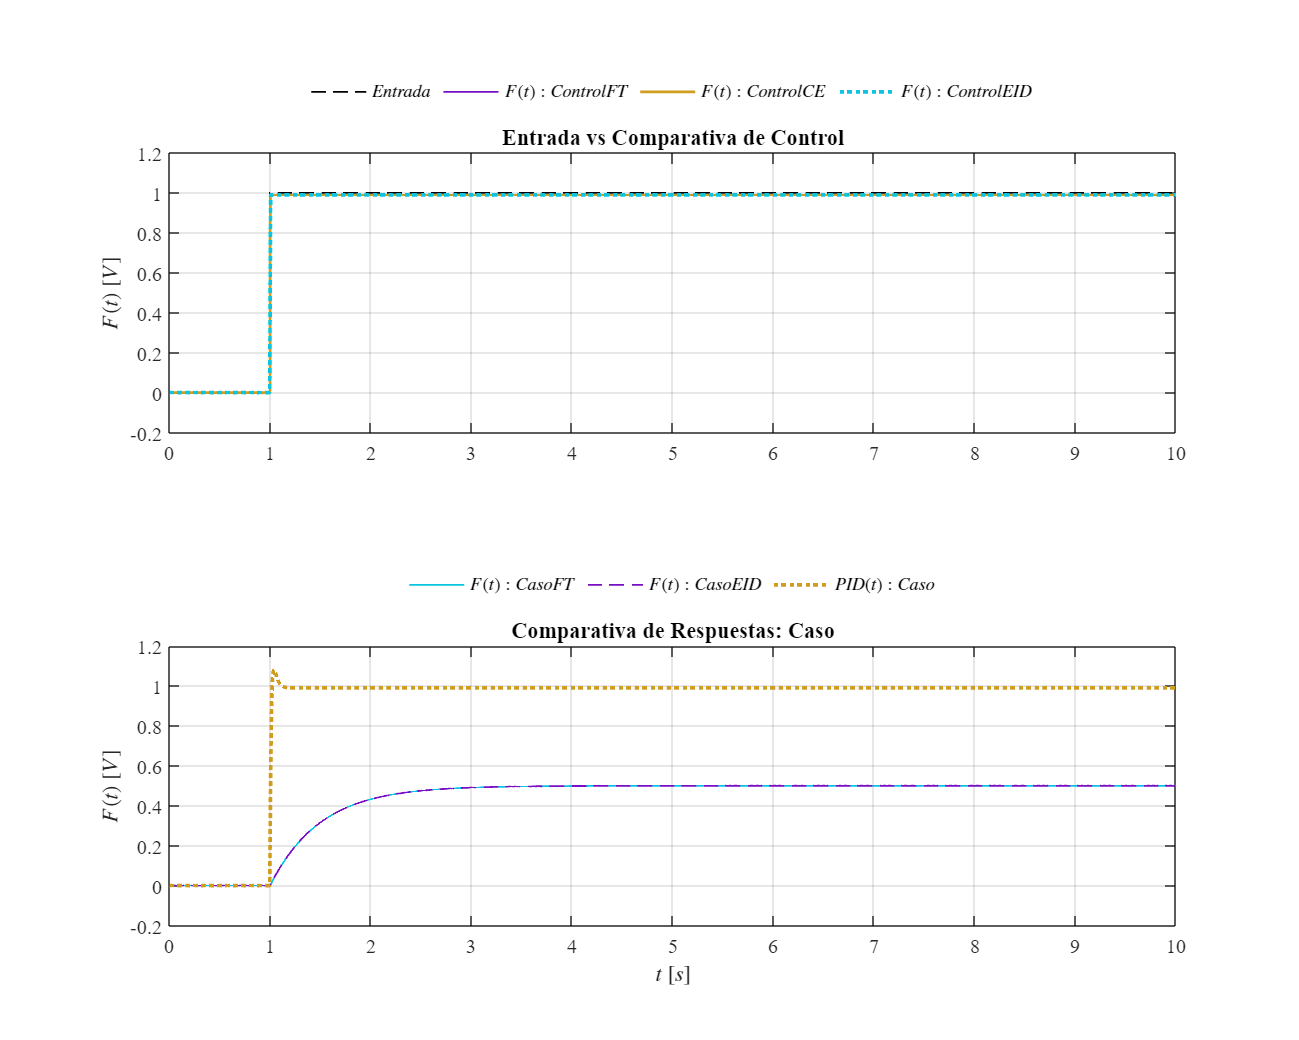

plotsignals(x.t, x.Fe, x.Fs1, x.Fs2, x.Fs3, x.Fs4, x.Fs5, x.PID)

## Funcion de las señales

function plotsignals(t, Fe, Fs1, Fs2, Fs3, Fs4, Fs5, PID)
    set(figure(), 'Color', 'w') 
    set(gcf, 'units', 'centimeters', 'position', [1,1,25,20]) 
    
    % Paleta de colores original [cite: 81-83]
    powerrangers = [10,196,224; 120,14,197; 208,157,31]/255;
    colororder(powerrangers) 

    %% Subplot 1: Comparativa de Control (FT vs CE vs EID)
    subplot(2,1,1); box on; hold on; 
    plot(t, Fe, 'k--', 'LineWidth', 1); % Entrada
    plot(t, Fs1, '-', 'LineWidth', 1);   % Control FT
    plot(t, Fs2, '-', 'LineWidth', 1.5); % Control CE (RLC)
    plot(t, Fs3, ':', 'LineWidth', 2);   % Control EID
    
    L1 = legend('$Entrada$', '$F(t): Control FT$', '$F(t): Control CE$', '$F(t): Control EID$');
    set(L1, 'Interpreter', 'Latex', 'FontSize', 10, 'location', 'NorthOutside', 'Orientation', 'Horizontal', 'box', 'off') 
    
    ylabel('$F(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11) 
    title("Entrada vs Comparativa de Control"); 
    xlim([0, 10]); xticks(0:1:10); grid on;
    ylim([-0.2, 1.2]); yticks(-0.2:0.2:1.2); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

    %% Subplot 2: Respuesta del Caso (FT vs EID vs PID)
    subplot(2,1,2); box on; hold on; 
    plot(t, Fs4, '-', 'LineWidth', 1);   % Caso FT
    plot(t, Fs5, '--', 'LineWidth', 1);  % Caso EID
    plot(t, PID, ':', 'LineWidth', 2);   % PID Caso
    
    L2 = legend('$F(t): Caso FT$', '$F(t): Caso EID$', '$PID(t): Caso$');
    set(L2, 'Interpreter', 'Latex', 'FontSize', 10, 'location', 'NorthOutside', 'Orientation', 'Horizontal', 'box', 'off') 
    
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11) 
    ylabel('$F(t)$ $[V]$', 'Interpreter', 'Latex', 'FontSize', 11) 
    title("Comparativa de Respuestas: Caso"); 
    xlim([0, 10]); xticks(0:1:10); grid on;
    ylim([-0.2, 1.2]); yticks(-0.2:0.2:1.2); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

    % Exportación opcional
    exportgraphics(gcf, 'Graficas Endocrino.pdf', 'ContentType', 'vector')
end